% % Dynamics
% clear L PSM psmdyn;
% 
% % Symbilic, find the regressor
% L(1)=Link('revolute','d',0,'a',0,'alpha',sym(pi/2),'offset',sym(pi/2));
% L(2)=Link('revolute','d',0,'a',0,'alpha',sym(-pi/2),'offset',sym(-pi/2));
% L(3)=Link('prismatic','theta',0,'a',0,'alpha',sym(pi/2),'offset',-0.4318);
% L(4)=Link('revolute','d',0.4162,'a',0,'alpha',0,'offset',0);
% L(5)=Link('revolute','d',0,'a',0,'alpha',sym(-pi/2),'offset', sym(-pi/2));
% L(6)=Link('revolute','d',0,'a',0.0091,'alpha',sym(-pi/2),'offset',sym(-pi/2));
% 
% L(1).mdh=1;
% L(2).mdh=1;
% L(3).mdh=1;
% L(4).mdh=1;
% L(5).mdh=1;
% L(6).mdh=1;
% PSM = SerialLink(L)

 
PSM = 
 
noname:: 6 axis, RRPRRR, modDH, slowRNE, Symbolic                
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|       pi/2|       pi/2|
|  2|         q2|          0|          0|      -pi/2|      -pi/2|
|  3|          0|         q3|          0|       pi/2|    -0.4318|
|  4|         q4|     0.4162|          0|          0|          0|
|  5|         q5|          0|          0|      -pi/2|      -pi/2|
|  6|         q6|          0|     0.0091|      -pi/2|      -pi/2|
+---+-----------+-----------+-----------+-----------+-----------+
 


% psmdyn = RobotDynamics(PSM);
% psmdyn.initSymbolicParams();

% psmdyn.calculateEnergy();

calculating kinetic energy for link 1
Simplifying
calculating kinetic energy for link 2
Simplifying
calculating kinetic energy for link 3
Simplifying
calculating kinetic energy for link 4
Simplifying
calculating kinetic energy for link 5
Simplifying
calculating kinetic energy for link 6
Simplifying
calculating potential energy for link 1
Simplifying
calculating potential energy for link 2
Simplifying
calculating potential energy for link 3
Simplifying
calculating potential energy for link 4
Simplifying
calculating potential energy for link 5
Simplifying
calculating potential energy for link 6
Simplifying


% psmdyn.calculateJointTorque();

calculating joint torque for link 1
calculating gravity term for link 1
calculating joint torque for link 2
calculating gravity term for link 2
calculating joint torque for link 3
calculating gravity term for link 3
calculating joint torque for link 4
calculating gravity term for link 4
calculating joint torque for link 5
calculating gravity term for link 5
calculating joint torque for link 6
calculating gravity term for link 6


% psmdyn.calculateModelMatrices();

calculating M matrix
calculating M matrix line 1
calculating M matrix line 2
calculating M matrix line 3
calculating M matrix line 4
calculating M matrix line 5
calculating M matrix line 6
calculating C matrix


% M = psmdyn.M;
% for i=1:6
%     for j=1:6
%         pause(.1);
%         printStatus(i,j);
%         M(i,j) = simplify(M(i,j));
%     end
% end

processing:   6   6

% C = psmdyn.C;
% for i=1:6
%     pause(.1);
%     printStatus(i,0);
%     C(i) = simplify(C(i));
% end

processing:   6   0

% G = psmdyn.G;
% for i=1:6
%     pause(.1);
%     printStatus(i,0);
%     G(i) = simplify(G(i));
% end

processing:   6   0

% psmdyn.calculateRegressor();

calculating Y for joint 1
calculating Y for joint 2
calculating Y for joint 3
calculating Y for joint 4
calculating Y for joint 5
calculating Y for joint 6


% Y = psmdyn.Y;
% for i=1:6
%     for j=1:60
%         pause(.1);
%         printStatus(i,j);
%         Yij = simplify(Y(i,j));
% %         save("./Y/Y"+string(i)+"_"+string(j), "Yij");
%         Y(i,j)=Yij;
%     end
% end

processing:   6  60

% psmdyn.Y = Y;

% psmdyn.findIndependentRegressor();

Random sampling
Progress: 120/120
Computing...


% Yb = psmdyn.Yb;
% Yb_fun = matlabFunction(Yb,'Vars',[psmdyn.q,psmdyn.dq,psmdyn.ddq,g],'File','Yb_fun')

% vpa(psmdyn.baseParams,4)

$$ans = \left(\begin{array}{c} \mathrm{l6y}\\ \mathrm{l6x}\\ m_{3}+m_{4}+m_{5}+m_{6}\\ \mathrm{l5y}+\mathrm{l6z}\\ \mathrm{l5x}+0.0091\,m_{6}\\ \mathrm{L6xy}\\ \mathrm{l4y}+\mathrm{l5z}\\ \mathrm{L6xz}\\ \mathrm{l4x}\\ \mathrm{L6yz}\\ \mathrm{l3z}+\mathrm{l4z}+0.4162\,m_{4}+0.4162\,m_{5}+0.4162\,m_{6}\\ \mathrm{l3x}\\ \mathrm{L5xy}-0.0091\,\mathrm{l6z}\\ \mathrm{L5yz}\\ \mathrm{L5xz}\\ \mathrm{L5xx}+\mathrm{L6xx}+\mathrm{L4zz}\\ \mathrm{l3y}\\ \mathrm{L6zz}\\ \mathrm{L4xy}\\ \mathrm{L4xz}\\ \mathrm{l1x}\\ \mathrm{L5xx}+\mathrm{L6yy}+\mathrm{L4zz}\\ \mathrm{L4yz}\\ \mathrm{l2y}\\ \mathrm{l2x}\\ \mathrm{L5zz}-1.0\,\mathrm{L4zz}-1.0\,\mathrm{L5xx}+8.281e-5\,m_{6}\\ \mathrm{L2xy}-1.0\,\mathrm{L3xz}\\ \mathrm{l1y}+\mathrm{l2z}\\ \mathrm{L5yy}+\mathrm{L4zz}+8.281e-5\,m_{6}\\ \mathrm{L2xz}+\mathrm{L3xy}\\ \mathrm{L4xx}+\mathrm{L3yy}+\mathrm{L2zz}-1.0\,\mathrm{L4zz}-0.8324\,\mathrm{l3z}-0.1732\,m_{4}-0.1732\,m_{5}-0.1732\,m_{6}\\ \mathrm{L3yz}-1.0\,\mathrm{L2yz}\\ \mathrm{L3yy}+\mathrm{L4yy}+\mathrm{L2zz}-0.8324\,\mathrm{l3z}-0.1732\,m_{4}-0.1732\,m_{5}-0.1732\,m_{6}\\ \mathrm{L2yy}+\mathrm{L1zz}+\mathrm{L3zz}\\ \mathrm{L2xx}+\mathrm{L3xx}-1.0\,\mathrm{L3yy}+\mathrm{L1zz}-1.0\,\mathrm{L2zz} \end{array}\right)$$

clear PSM L psmdyn
% L(1)=Link('revolute','d',0,'a',0,'alpha',pi/2,'offset',pi/2);
% L(2)=Link('revolute','d',0,'a',0,'alpha',-pi/2,'offset',-pi/2);
% L(3)=Link('prismatic','theta',0,'a',0,'alpha',pi/2,'offset',-0.4318);
% L(4)=Link('revolute','d',0.4162,'a',0,'alpha',0,'offset',0);
% L(5)=Link('revolute','d',0,'a',0,'alpha',-pi/2,'offset', -pi/2);
% L(6)=Link('revolute','d',0,'a',0.0091,'alpha',-pi/2,'offset',-pi/2);

% Use symbolic pi to make simplify() possible
L(1)=Link('revolute','d',0,'a',0.36,'alpha',0,'offset',0);
L(2)=Link('revolute','d',0,'a',0,'alpha',sym(-pi/2),'offset',0);
L(3)=Link('revolute','d',0,'a',0.42,'alpha',sym(pi/2),'offset',0);
L(4)=Link('revolute','d',0,'a',0,'alpha',sym(pi/2),'offset',0);
L(5)=Link('revolute','d',0,'a',0.4,'alpha',sym(-pi/2),'offset',0);
L(6)=Link('revolute','d',0,'a',0,'alpha',sym(-pi/2),'offset',0);
L(7)=Link('revolute','d',0,'a',0.126,'alpha',sym(pi/2),'offset',0);

L(1).mdh=1;
L(2).mdh=1;
L(3).mdh=1;
L(4).mdh=1;
L(5).mdh=1;
L(6).mdh=1;
L(7).mdh=1;

% L1 = eye(3);
% l = [1,1,1];
% m = 2;
% r = l./m;
% I1 = L2I(L1,m,r);

m = [3.94781, 4.50275, 2.45520, 2.61155, 3.41000, 3.38795, 0.35432;];

r = [-0.00351, 0.00160, -0.03139;
    -0.00767, 0.16669, -0.00355;
    -0.00225,-0.03492,-0.02652;
    0.00020,-0.05268,0.03818;
    0.00005,-0.00237,-0.21134;
    0.00049,0.02019,-0.02750;
    -0.03466,-0.02324,0.07138]

r =    -0.0035    0.0016   -0.0314
   -0.0077    0.1667   -0.0036
   -0.0022   -0.0349   -0.0265
    0.0002   -0.0527    0.0382
    0.0001   -0.0024   -0.2113
    0.0005    0.0202   -0.0275
   -0.0347   -0.0232    0.0714



IVec = [0.00455, 0, 0, 0.00454, 0.00001, 0.00029;
    0.00032, 0, 0, 0.00010, 0, 0.00042;
    0.00223, -0.00005, 0.00007, 0.00219, 0.00007, 0.00073;
    0.03844, 0.00088, -0.00112, 0.01144, -0.00111, 0.04988;
    0.00277, -0.00001, 0.00001, 0.00284, 0, 0.00012;
    0.00050, -0.00005, -0.00003, 0.00281, -0.00004, 0.00232;
    0.00795, 0.00022, -0.00029, 0.01089, -0.00029, 0.00294]

IVec =     0.0046         0         0    0.0045    0.0000    0.0003
    0.0003         0         0    0.0001         0    0.0004
    0.0022   -0.0001    0.0001    0.0022    0.0001    0.0007
    0.0384    0.0009   -0.0011    0.0114   -0.0011    0.0499
    0.0028   -0.0000    0.0000    0.0028         0    0.0001
    0.0005   -0.0001   -0.0000    0.0028   -0.0000    0.0023
    0.0080    0.0002   -0.0003    0.0109   -0.0003    0.0029



L(1).I=IVec2Tensor(IVec(1,:));
L(1).r=r(1,:);
L(1).m=m(1);

L(2).I=IVec2Tensor(IVec(2,:));
L(2).r=r(2,:);
L(2).m=m(2);

L(3).I=IVec2Tensor(IVec(3,:));
L(3).r=r(3,:);
L(3).m=m(3);

L(4).I=IVec2Tensor(IVec(4,:));
L(4).r=r(4,:);
L(4).m=m(4);

L(5).I=IVec2Tensor(IVec(5,:));
L(5).r=r(5,:);
L(5).m=m(5);

L(6).I=IVec2Tensor(IVec(6,:));
L(6).r=r(6,:);
L(6).m=m(6);

L(7).I=IVec2Tensor(IVec(7,:));
L(7).r=r(7,:);
L(7).m=m(7);

%L(3).qlim=[0,5];

PSM = SerialLink(L)

 
PSM = 
 
noname:: 7 axis, RRRRRRR, modDH, slowRNE                         
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|       0.36|          0|          0|
|  2|         q2|          0|          0|      -pi/2|          0|
|  3|         q3|          0|       0.42|       pi/2|          0|
|  4|         q4|          0|          0|       pi/2|          0|
|  5|         q5|          0|        0.4|      -pi/2|          0|
|  6|         q6|          0|          0|      -pi/2|          0|
|  7|         q7|          0|      0.126|       pi/2|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


% PSM.plot([0,0,1,0,0,0])

test = [1,2,3,4,5,6,7];
tau = double(PSM.rne(test,test,test,'gravity',[0,0,9.81]))

tau =    33.6102   72.3037  -23.4872   45.3069   -1.7656   -0.7906   -0.0174


psmdyn = RobotDynamics(PSM);

psmdyn.calculateEnergy();

calculating kinetic energy for link 1
Simplifying
calculating kinetic energy for link 2
Simplifying
calculating kinetic energy for link 3
Simplifying
calculating kinetic energy for link 4
Simplifying
calculating kinetic energy for link 5
Simplifying


psmdyn.calculateJointTorque();

calculating joint torque for link 1
calculating gravity term for link 1
calculating joint torque for link 2
calculating gravity term for link 2
calculating joint torque for link 3
calculating gravity term for link 3
calculating joint torque for link 4
calculating gravity term for link 4
calculating joint torque for link 5
calculating gravity term for link 5
calculating joint torque for link 6
calculating gravity term for link 6


psmdyn.calculateModelMatrices();

calculating M matrix
calculating M matrix line 1
calculating M matrix line 2
calculating M matrix line 3
calculating M matrix line 4
calculating M matrix line 5
calculating M matrix line 6
calculating C matrix


syms g
test = [0,0,0,0,0,0,0]

test =      0     0     0     0     0     0     0


tau = double(subs(psmdyn.tau,[psmdyn.q,psmdyn.dq,psmdyn.ddq,g], [[1,1,0.5+0.4318,1,1,1,1],test,test,9.81]))

Unable to resolve the name psmdyn.tau.

M = psmdyn.M;
C = psmdyn.C;
G = psmdyn.G;

M_fun_num = matlabFunction(M,'File','M_fun')

M_fun_num = function_handle with value:
    @M_fun


C_fun_num = matlabFunction(C,'Vars',[psmdyn.q,psmdyn.dq],'File','C_fun')

C_fun_num = function_handle with value:
    @C_fun


G_fun_num = matlabFunction(G,'Vars',[psmdyn.q,g],'File','G_fun')

G_fun_num = function_handle with value:
    @G_fun


tspan = [0 10];
y0 = [1,1,0.5+0.4318,1,1,1,0,0,0,0,0,0];
% solveRobotSimulation(0,y0,@M_fun,@C_fun,@G_fun,tau)
[t,y] = ode45(@(t,y) solveRobotSimulation(t,y,@M_fun_num,@C_fun_num,@G_fun_num,tau),tspan,y0)

t =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0002
    0.0002
    0.0004


y =     1.0000    1.0000    0.9318    1.0000    1.0000    1.0000         0         0         0         0         0         0
    1.0000    1.0000    0.9318    1.0000    1.0000    1.0000    0.0000    0.0000   -0.0001   -0.0000    0.0000   -0.0000
    1.0000    1.0000    0.9318    1.0000    1.0000    1.0000    0.0000    0.0000   -0.0001   -0.0000    0.0000   -0.0000
    1.0000    1.0000    0.9318    1.0000    1.0000    1.0000    0.0000    0.0000   -0.0002   -0.0000    0.0000   -0.0000
    1.0000    1.0000    0.9318    1.0000    1.0000    1.0000    0.0000    0.0000   -0.0002   -0.0000    0.0000   -0.0000
    1.0000    1.0000    0.9318    1.0000    1.0000    1.0000    0.0000    0.0000   -0.0005   -0.0000    0.0000   -0.0000
    1.0000    1.0000    0.9318    1.0000    1.0000    1.0000    0.0000    0.0000   -0.0007   -0.0000    0.0000   -0.0000
    1.0000    1.0000    0.9318    1.0000    1.0000    1.0000    0.0000    0.0000   -0.0010   -0.0000    0.0000   -0.0000
    1.0000    1.0000    0.93

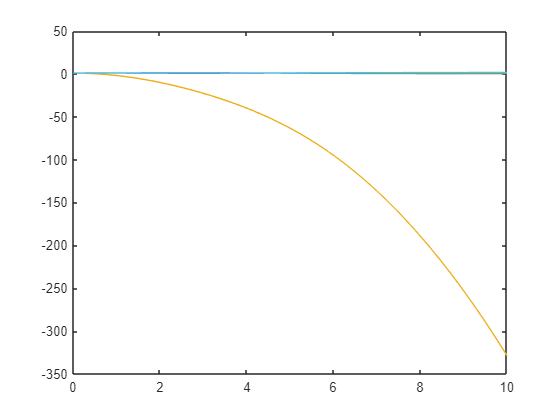

plot(t,y(:,1:6))

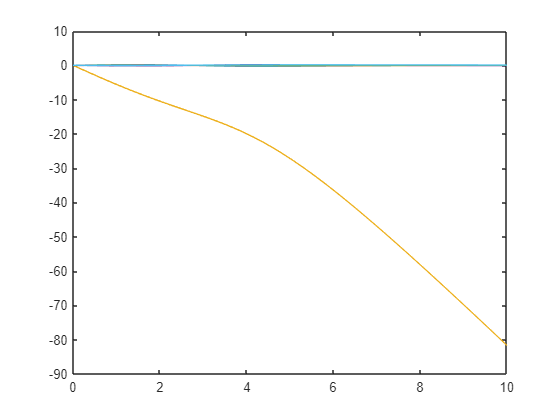

plot(t,y(:,7:12))

function printStatus (i,j)
    if i == 1 && j==1
        % The very first time we don't need to delete the old text
        fprintf('processing: %3d %3d', i,j);
    else
        % Each \b removes one character from the previous fprintf.
        fprintf('\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\bprocessing: %3d %3d', i,j);
    end
end